# Wideband Beamforming

This example shows how to perform wideband beamforming.

## Define a chirp waveform

close all

fs = 100e6;
t = (0:999).'/fs;
s = chirp(t,0,1e-4,fs);
az_in = 30;                     % incoming direction

% try other directions, for example
% az_in = 45;

## Simulate signal received by an array

fc = 300e6;                     % operating frequency
c = physconst("lightspeed");    % propagation speed
antArray = phased.ULA("NumElements",5,"ElementSpacing",c/(2*fc));
sigCollector = phased.WidebandCollector("Sensor",antArray,"SampleRate",fs,...
    "CarrierFrequency",fc,"PropagationSpeed",c);
x = sigCollector(s,az_in);

## Add receiver noise

rx = phased.Receiver("Gain",0,"NoiseMethod","Noise figure",...
    "NoiseFigure",125);
xn = rx(x);

## Define beamformer

bf = phased.SubbandPhaseShiftBeamformer(...
    "SensorArray",antArray,"SampleRate",fs,...
    "OperatingFrequency",fc,...
    "Direction",[az_in;0],"PropagationSpeed",c,...
    "WeightsOutputPort",true,"SubbandsOutputPort",true);

## Perform beamforming

[y,w,freq] = bf(xn);

## Plots

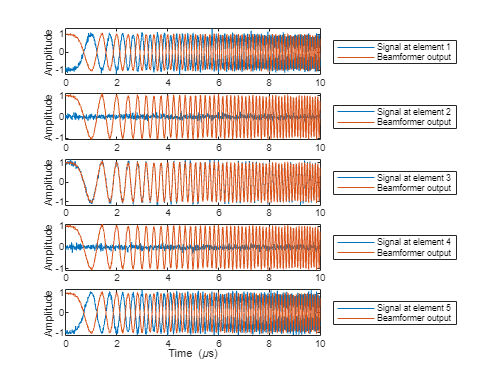

figure(1)
for i=1:5
    subplot(5,1,i)
    plot(1e6*t,real([xn(:,i) y])); % plot x to visualize signal without noise
    ylabel("Amplitude");
    legend("Signal at element "+i,"Beamformer output", ...
        "Location","EastOutside");
end
xlabel("Time (\mus)")

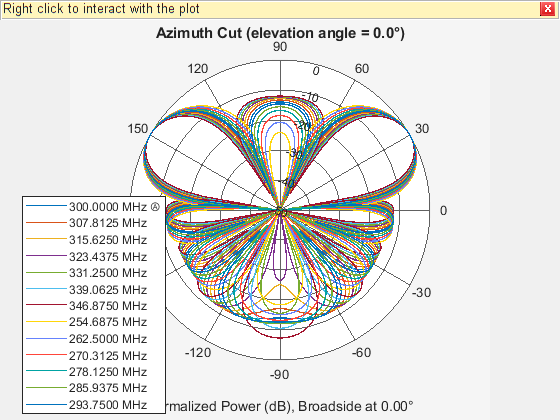


figure(2)
pattern(antArray,freq(1:5:end).',-180:180,0,"Weights",w(:,1:5:end),...
    "PropagationSpeed",c,"Type","powerdb","PlotStyle","overlay");